%======================================================================
% ECSE 443 - Final Project
% Author ----- Tristan Bouchard
% Student ID - 260747124
% Submitted -- Friday, April 12 2019, 17h00
%======================================================================
close all
clear
addpath('./Functions/');
format long

%======================================================================
% Question 1 - Single-Variable Integration
%======================================================================
syms x;
f(x) = 1/(exp(x)+exp(-x))

$$f(x) = \frac{1}{{\mathrm{e}}^{-x}+{\mathrm{e}}^{x}}$$

q1TrueVal = int(f,x,0,inf);
disp("The true value of the integral of f(x), using the" ...
    + " built-in MATLAB function int(), " + newline + "with a precision of 10^-6= " ...
    + string(vpa(q1TrueVal, 6)));

The true value of the integral of f(x), using the built-in MATLAB function int(), 
with a precision of 10^-6= 0.785398


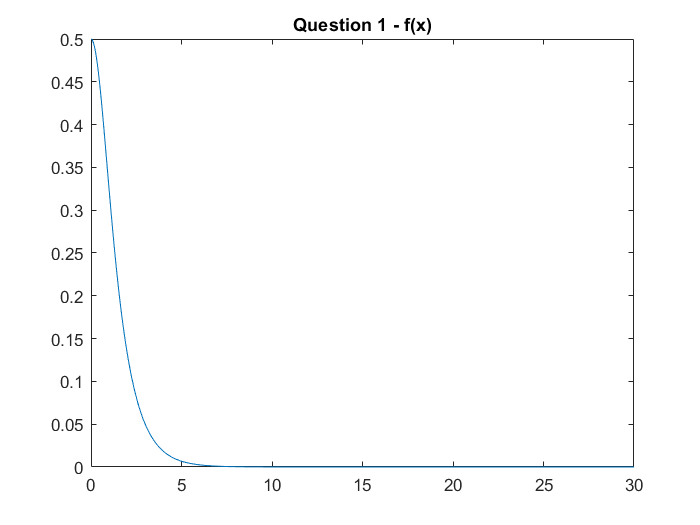


t = [0 30];
fplot(f, t);
title("Question 1 - f(x)")


% Using The Simpson Method, we can estimate that he value of the function
% past 100 is not relevant to the actual sum of the integral, as it is very
% close to zero
fDouble = @(x_) (1/(exp(x_)+exp(-x_)))

fDouble = function_handle with value:
    @(x_)(1/(exp(x_)+exp(-x_)))


[valSimpQ1, simpInterval] = simpsonIntegral(fDouble, 0, 30, q1TrueVal, 10^(-7));
disp("The computed value of the integral of f(x) using the Simpson " + ...
    "method = " +newline + string(vpa(valSimpQ1, 15)) +".");

The computed value of the integral of f(x) using the Simpson method = 
0.785398088205527.


err = relativeError(double(q1TrueVal), valSimpQ1);
disp("With an error of " + err);

With an error of -9.5737e-08


disp("This result was computed using " + (length(simpInterval) -1) + " segments of length " +...
    (simpInterval(2) - simpInterval(1)) + " each.");

This result was computed using 50 segments of length 0.6 each.


%======================================================================
% Question 2 - Single-Variable Integration
%======================================================================
clear
f2Double = @(x_) (x_^3)/((1-x_^2)^(1/2));

% In order to perform this with a set amount of divisions, I had to pull
% code out of the function I wrote for assignment 4

% First, subdivide the integration area into smaller areas.
lowerBound = 0;
upperBound = 1;
% Set starting amounts
divisions = 100;
range = upperBound - lowerBound;
intervalLength = range/divisions;
intervalEnds = [lowerBound: intervalLength:upperBound];

% Create for loop, to iterate through intervals'
sum = 0;
for i = 1:(length(intervalEnds)-1)
    lb = intervalEnds(i);
    ub = intervalEnds(i+1);
    % Compute the midpoint value of the bound
    midPtVal = (ub - lb)*f2Double((ub+lb)/2);
    sum = sum + midPtVal;
end

func2Value = sum;
intervals2 = intervalEnds;

disp("The computed value of the integral of f(x) using the Mid-point " + ...
    "method = " +newline + string(vpa(func2Value, 15)) +".");

The computed value of the integral of f(x) using the Mid-point method = 
0.623775746323755.



disp("This result was computed using " + (length(intervals2) -1) + " segments of length " +...
    (intervals2(2) - intervals2(1)) + " each.");

This result was computed using 100 segments of length 0.01 each.


%======================================================================
% Question 3 - Double Variable Integration - Gauss's Law
%======================================================================
clear
% Left side of gauss, 12.4 micro Coulombs per meter
gaussLeft = 12.4 * 10^(-6);
f3line = @(xval_) 12.4 * 10^(-6);

% I choose to integrate this using the Midpoint method, as the function is
% constant.
lowerBound = -2;
upperBound = 2;
% Set starting amounts
divisions = 400;
range = upperBound - lowerBound;
intervalLength = range/divisions;
intervalEnds = [lowerBound: intervalLength:upperBound];

% Create for loop, to iterate through intervals'
sum = 0;
for i = 1:(length(intervalEnds)-1)
    lb = intervalEnds(i);
    ub = intervalEnds(i+1);
    % Compute the midpoint value of the bound
    midPtVal = (ub - lb)*f3line((ub+lb)/2);
    sum = sum + midPtVal;
end

func3Value = sum;
intervals3 = intervalEnds;

disp("The computed value of the integral of f(x) using the Mid-point " + ...
    "method = " +newline + string(vpa(func3Value, 15)) +".");

The computed value of the integral of f(x) using the Mid-point method = 
0.0000496000000000001.



disp("This result was computed using " + (length(intervals3) -1) + " segments of length " +...
    (intervals3(2) - intervals3(1)) + " each.");

This result was computed using 400 segments of length 0.01 each.


% Then, determine the pattern of the electric field caused by a wire of
% charge on a sphere of 2m in radius
% Set up initial conditions
% Copy code from Simpson method
func = @intFunc3;
lowerBoundX = 0;
upperBoundX = 2*pi;
lowerBoundY = @(x) 0;
upperBoundY = @(x) pi ;
trueValue = func3Value

trueValue =      4.960000000000009e-05


precision = 10^(-5);
stepStart = 10;

[integralRight3, intervals3] = integralSimpsonDouble(func, lowerBoundX, upperBoundX, lowerBoundY, upperBoundY, trueValue, precision, stepStart);

For 10 divisions, the integral = 4.96e-05
With an absolute error of 1.6825e-10
Elapsed time is 0.007195 seconds.



disp("The computed value of the integral of f(x) using the Simpson " + ...
    "method = " +newline + string(vpa(integralRight3, 15)) +".");

The computed value of the integral of f(x) using the Simpson method = 
0.0000496001682541567.


errorCompSimp = absoluteError(trueValue,integralRight3);
disp("The computed error between the actual result and what was computed = " + double(errorCompSimp));

The computed error between the actual result and what was computed = 1.6825e-10


disp("This result was computed using " + (length(intervals3) -1) + " segments of area " + ...
    (intervals3(2) - intervals3(1)) + " by " + (intervals3(2) - intervals3(1)) + " each.");

This result was computed using 10 segments of area 0.62832 by 0.62832 each.


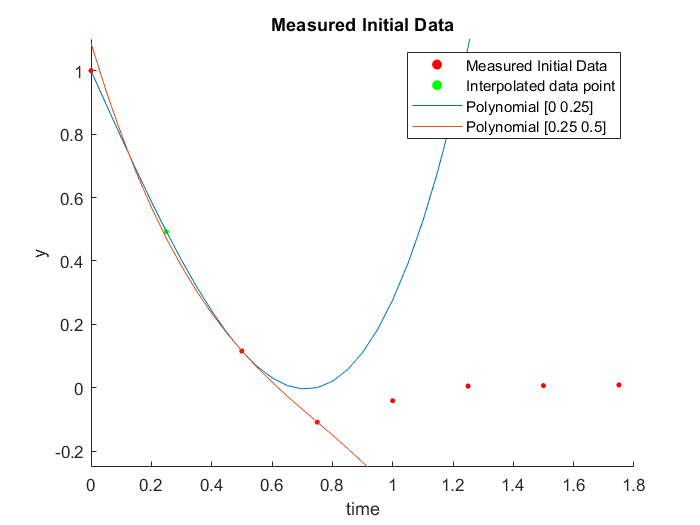

%======================================================================
% Question 4 - Second order response: Interpolation and curve fitting
%======================================================================
clear 
% u(t) = 0, -inf < t < 0
%      = 1, 0 < t < inf
time = [0 0.5 0.75 1 1.25 1.5 1.75]';
points = [1 0.1160 -0.1084 -0.0409 0.0052 0.0067 0.009]';
data = [time points];

% Use the forward and backward difference methods explored in assignment 4, as well as the
% Euler method

% First, I will interpolate using my cubic spline function from assignment
% 3 to find a value for t = 0.25.
coeff = cubicSpline(data(1, :), data(2, :), data(3, :));

t=[0:0.05:2.5];
func1 = coeff(1,1) + coeff(1,2)*t + coeff(1,3)*t.^2 + coeff(1,4)*t.^3;
func2 = coeff(2,1) + coeff(2,2)*t + coeff(2,3)*t.^2 + coeff(2,4)*t.^3;

inter = func1(6);

legendTitles = ["Measured Initial Data", "Interpolated data point"];
plotTitle = "Measured Initial Data";
yScale = [-0.25 1.1];

interp = [0.25 inter];
% Plot the data points
plotData(data, interp, "No Data", legendTitles, plotTitle, yScale);
hold on
plot(t, func1);
plot(t, func2);
legend("Measured Initial Data", "Interpolated data point", "Polynomial [0 0.25]", "Polynomial [0.25 0.5]")
hold off


% Using the interpolated data point, create new data:
time = [0:0.25:1.75]';
points = [1 inter 0.1160 -0.1084 -0.0409 0.0052 0.0067 0.009]';
data = [time points];
h = 0.25;
% Form A matrix
% We know that a particular row = [f'' f' f]
firstDevFwd = @(i) (points(i+1) - points(i))/h;
secondDevFwd = @(i) (points(i+2) - 2*points(i+1) + points(i))/(h^2);
firstDevBwd = @(i) (points(i) - points(i-1))/h;
secondDevBwd = @(i) (points(i) - 2*points(i-1) + points(i-2))/(h^2);
f = @(i) points(i);

A = [secondDevFwd(1) firstDevFwd(1) f(1);...
     secondDevFwd(2) firstDevFwd(2) f(2);...
     secondDevFwd(3) firstDevFwd(2) f(3);...
     secondDevFwd(4) firstDevFwd(2) f(4);...
     secondDevFwd(5) firstDevFwd(2) f(5);...
     secondDevFwd(6) firstDevFwd(2) f(6);...
     secondDevBwd(7) firstDevBwd(7) f(7);...
     secondDevBwd(8) firstDevBwd(8) f(8)...
    ];
siz = size(data);
yValues = ones(siz(1),1);
% solve the normalized system of equations according to the formula:
a = (A'*A)\(A'*yValues);

% Plot the newly found function

%======================================================================
% Question 5 - LU factorization
%======================================================================
clear

points = [3 -5 47 20;...
          11 16 17 10;...
          56 22 11 -18;...
          17 66 -12 7
         ];
yValues = [18 26 34 82]';

% Obtain the upper and lower matrices for the datapoints
[LMatrix, UMatrix] = LUfactorization(points);
disp(LMatrix);

   1.000000000000000                   0                   0                   0
   3.666666666666667   1.000000000000000                   0                   0
  18.666666666666668   3.359223300970875   1.000000000000000                   0
   5.666666666666667   2.747572815533981  -0.430890185138220   1.000000000000000



disp(UMatrix);

   1.0e+02 *

   0.030000000000000  -0.050000000000000   0.470000000000000   0.200000000000000
                   0   0.343333333333333  -1.553333333333333  -0.633333333333333
                   0                   0  -3.445339805825242  -1.785825242718447
                   0                   0                   0  -0.092698452954603




%Solve for system by multiplying the two matrices, L*U
soln = inv(UMatrix)* inv(LMatrix) * [yValues]

soln =   -1.077179830921179
   1.990205466334710
   1.474706574375529
  -1.906432108560638



% Plug values back into the equations and solve for Y:
yValsComputed = points*soln

yValsComputed =   18.000000000000021
  25.999999999999996
  33.999999999999879
  81.999999999999957



exactSoln = points\yValues

exactSoln =   -1.077179830921178
   1.990205466334710
   1.474706574375529
  -1.906432108560639



% Compute Square error of the LU result
squareErr = (soln - exactSoln).^2

squareErr = 	1.0e+-29 *

   0.315544362088405
   0.004930380657631
   0.004930380657631
   0.123259516440783


%======================================================================
% Question 6 - Fixed Point Iteration
%======================================================================
% First attempt to perform some arithmetic on the matrix by shuffling
% around the rows of the matrix. We do this to have the greatest
% coefficients along the diagonal of the matrix
points = [56 22 11 -18;...
          17 66 -12 7;...
          3 -5 47 20;...
          11 16 17 10;...
         ]

points =     56    22    11   -18
    17    66   -12     7
     3    -5    47    20
    11    16    17    10



yValues = [34 82 18 26]'

yValues =     34
    82
    18
    26


augMatrix = [points yValues];

x1 = 0;
x2 = 0;
x3 = 0;
x4 = 0;
for i = 1:1000
    x1 = (yValues(1) - points(1,2)*x2 - points(1,3)*x3 - points(1,4)*x4)/(points(1,1));
    x2 = (yValues(2) - points(2,1)*x1 - points(2,3)*x3 - points(2,4)*x4)/(points(2,2));
    x3 = (yValues(3) - points(3,1)*x1 - points(3,2)*x2 - points(3,4)*x4)/(points(3,3));
    x4 = (yValues(4) - points(4,1)*x1 - points(4,2)*x2 - points(4,3)*x3)/(points(4,4));
end

disp(x1);

  -1.077179830921179



disp(x2);

   1.990205466334711



disp(x3);

   1.474706574375531



disp(x4);

  -1.906432108560642




squareErr2 = ([x1 x2 x3 x4]' - exactSoln).^2

squareErr2 = 	1.0e+-29 *

   0.177493703674728
   0.078886090522101
   0.241588652223935
   0.596576059573390


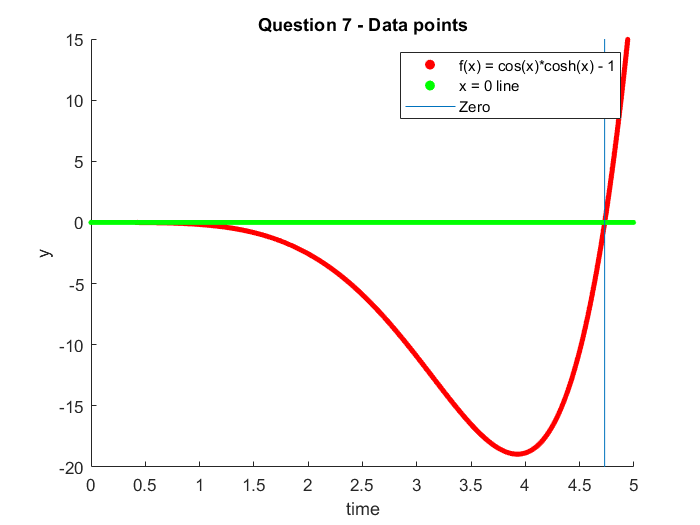

%======================================================================
% Question 7 - Secant Method root finding
%======================================================================
clear

% First, begin by plotting the function

f = @(x) cos(x).*cosh(x)-1;
t = 0:0.0001:5;

datapoints = f(t);
data = [t' double(datapoints)'];

zeroLine = 0 * t;
zeroL = [t' zeroLine'];
% Plot the data points

root = secantRootFinding(data, 4.5, 5, 10^(-4), 100);
pt = [root 0];
% Draw root line at x to show root
legendTitles = ["f(x) = cos(x)*cosh(x) - 1", "x = 0 line"];
plotTitle = "Question 7 - Data points";
yScale = [-20 15];
plotData(data, zeroL, "No Data", legendTitles, plotTitle, yScale);
hold on
lin = line([root root], yScale);
legend("f(x) = cos(x)*cosh(x) - 1", "x = 0 line", "Zero");
hold off


disp("The value of the zero is " + string(vpa(root,10)));

The value of the zero is 4.730040742


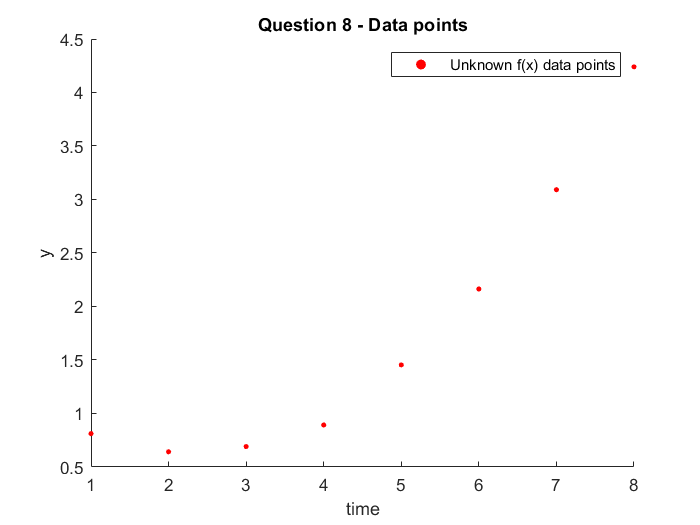

%======================================================================
% Question 8 - Polynomial curve fitting
%======================================================================
clear

time = [1:1:8];
dataPts= [0.812 0.642 0.691 0.893 1.454 2.164 3.092 4.24];
data = [time' dataPts'];
% Plot data
plotData(data, "No Data", "No Data", "Unknown f(x) data points", "Question 8 - Data points", [0.5 4.5]);

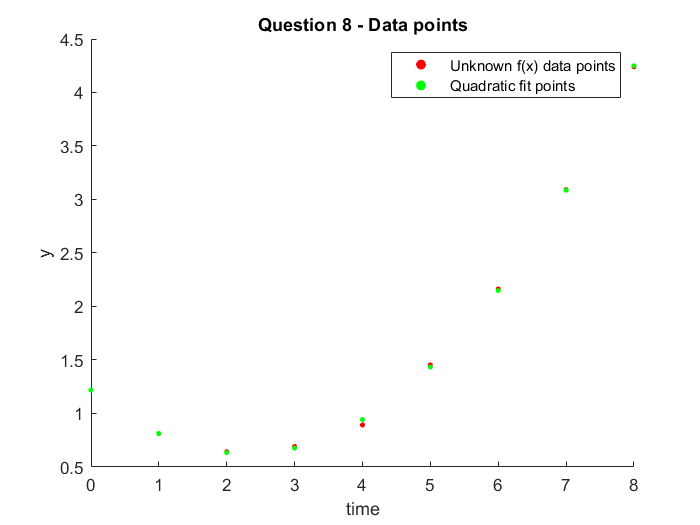


% Fit second order polynomial to datapoints
coefficientVector = fitQuadratic(data);

% Obtain data points from coefficients
t = [0:1:8];
dataQuad = computeQuadraticScatter(t', coefficientVector);

plotData(data, dataQuad, "No Data", ["Unknown f(x) data points", "Quadratic fit points"], "Question 8 - Data points", [0.5 4.5]);


% Compute error between points in question and points from quadratic fit
error = data(:, 2) - dataQuad(2:9, 2);

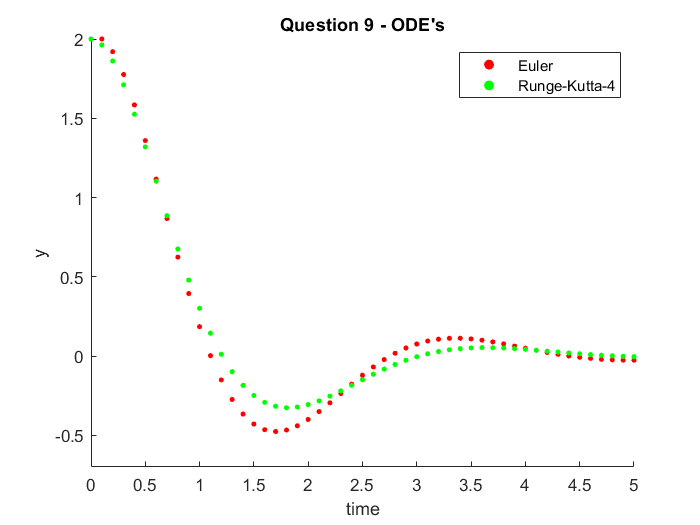

%======================================================================
% Question 9 - ODE's: Euler and Runge-Kutta-4 Methods
%======================================================================
clear

funcAt0 = 2;
funcPrimeAt0 = 0;

ufunc = @(t,u,y) u;
yfunc = @(t,u,y) -2*u-4*y;

h = 0.1;
t = 0:h:5;

% Perform Euler Method on ODE to obtain data points
eulerPoints = eulerODE(funcAt0, funcPrimeAt0, t, ufunc, yfunc);

% Perform Runge-Kutta-4 algorithm
rungeKutta4Points = rungeKutta4(funcAt0, funcPrimeAt0, t, ufunc, yfunc);

legends = ["Euler", "Runge-Kutta-4"];
titles = ["Question 9 - ODE's"];
plotData(eulerPoints(:, 1:2), rungeKutta4Points(:, 1:2), "No Data", legends, titles, [-0.7 2] );

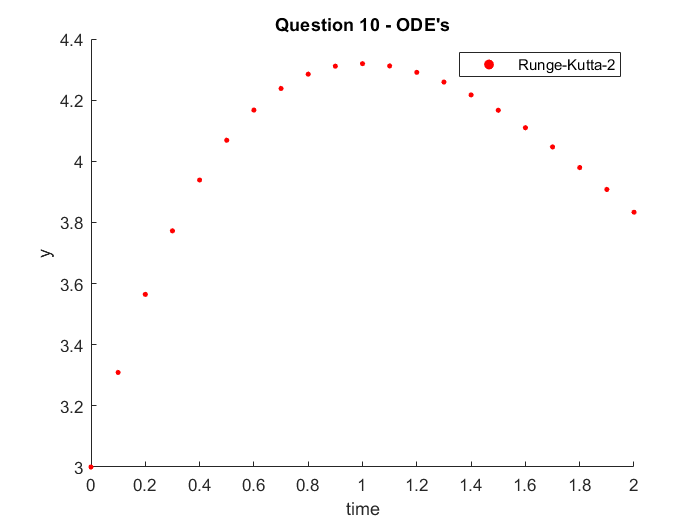

%======================================================================
% Question 10 - ODE's: Runge-Kutta-2 Method
%======================================================================
clear

h = 0.1;
t = 0:h:2;

ufunc = @(t,y) -1.2*y + 7*exp(-0.3*t);
y0 = 3;

rungeKutta2Points = rungeKutta2Heun(y0, t, ufunc);

legends = ["Runge-Kutta-2"];
titles = ["Question 10 - ODE's"];
plotData(rungeKutta2Points, "No Data", "No Data", legends, titles, [-0.7 2] );

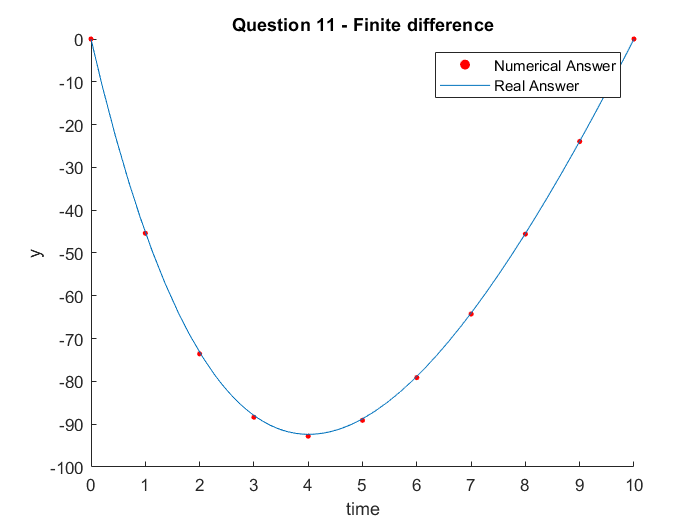

%======================================================================
% Question 11 - ODE's: BVP with Finite Difference Method
%======================================================================
clear

y0 = 0;
y10 = 0;
deltaX = 1;
%centDiff1st = @(x) (func(x+1) - func(x-1))/(2*deltaX);
%centDiff2nd = @(x) (func(x+1) - 2*func(x) + func(x+1))/(deltaX^2);
% Begin by solving for t(0), t(1), t(2) coefficients by hand, obtain
t0 = 7/8;
t1 = -2;
t2 = 9/8;

% Build Matrix: Needs to be 11 - 2 (outer points) = 9 by 9
A = [t1 t2  0 0 0 0 0 0 0;...
     t0 t1 t2 0 0 0 0 0 0;...
     0 t0 t1 t2 0 0 0 0 0;...
     0 0 t0 t1 t2 0 0 0 0;...
     0 0 0 t0 t1 t2 0 0 0;...
     0 0 0 0 t0 t1 t2 0 0;...
     0 0 0 0 0 t0 t1 t2 0;...
     0 0 0 0 0 0 t0 t1 t2;...
     0 0 0 0 0 0 0  t0 t1
    ];

xValues = [8 8 8 8 8 8 8 8 8]';

yValues = A\xValues;

dataPoints = [y0 yValues' y10];
time = [0:1:10];

data = [time' dataPoints'];


% Solve for real value
syms y(x)
Dy = diff(y);

ode = diff(y,x,2) + (1/4)*diff(y,x,1) == 8;
cond1 = y(0) == 0;
cond2 = y(10) == 0;

conds = [cond1 cond2];
ySol(x) = dsolve(ode,conds);
ySol = simplify(ySol);

plotData(data, "No Data", "No Data", "Numerical Answer" , "Question 11 - Finite difference", [-100 0]);
hold on
fplot(ySol, [0 10]);
legend("Numerical Answer", "Real Answer");
hold off

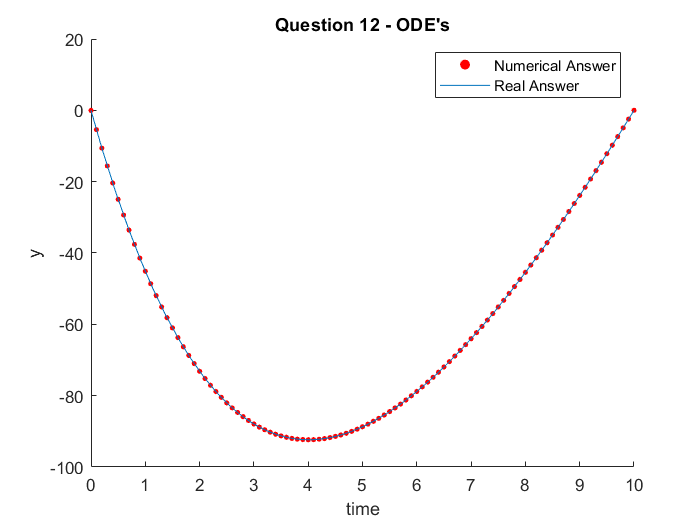

%======================================================================
% Question 12 - ODE's: BVP with Shooting Method
%======================================================================
clear

y0 = 0;
y10 = 0;
deltaX = 1;

% Convert equation into a pair of first order equations
ufunc = @(t,u,y) u;
yfunc = @(t,u,y) 8-u/4;

% Shooting method: interate over starting value for y'
yPrime = [-100:0.01:-25];
time = [0:0.1:10];
error = zeros(size(yPrime));
sz = size(yPrime);
for i = 1:sz(2)
    yP = yPrime(i);
    odePoints = rungeKutta4(y0,yP, time, ufunc, yfunc);
    tenthPt = odePoints(101,2);
    error(i) = abs(y10 - tenthPt); 
end
[minVal, index] = min(error);

yPrimeActual = yPrime(index);


% Solve for real value
syms y(x)
Dy = diff(y);

ode = diff(y,x,2) + (1/4)*diff(y,x,1) == 8;
cond1 = y(0) == 0;
cond2 = y(10) == 0;

conds = [cond1 cond2];
ySol(x) = dsolve(ode,conds);
ySol = simplify(ySol);

t = [0:0.1:10];
odePointsTrue = rungeKutta4(y0, yPrimeActual, t, ufunc, yfunc);
plotData(odePointsTrue, "No Data", "No Data", "Suh", "Question 12 - ODE's", [0 0]);
hold on
fplot(ySol, [0 10]);
legend("Numerical Answer", "Real Answer");
hold off